分回合展示事件记录

## 语法

## 示例

## 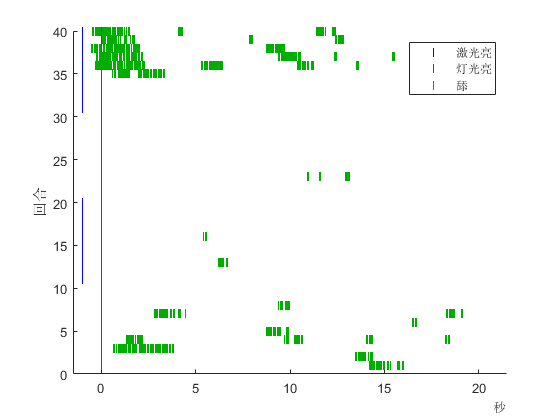

## 输入参数

EventLog tabular，事件记录表，至少包含以下列：

- Time(:,1)duration，从会话开始经历的时间

- Event(:,1)categorical，事件

TrialMarker(1,1)categorical，用于分割回合的标志性事件

TrialRange(1,2)duration，二元素向量分别表示回合开始和结束相对于TrialMarker的时间。例如seconds([-6,20])表示回合开始于TrialMarker前6秒，到后20秒为止。

ExcludedEvents(1,:)categorical=categorical.empty(1,0)，排除的事件，不会在图上显示出来

function TrialwiseEventPlot(EventLog,TrialMarker,TrialRange,ExcludedEvents)
arguments
	EventLog
	TrialMarker
	TrialRange
	ExcludedEvents=categorical.empty(1,0)
end
TrialEventIndices=find(EventLog.Event==TrialMarker);
EventLog.TrialIndex(:)=0x0;
for T=1:numel(TrialEventIndices)
	TrialTime=EventLog.Time(TrialEventIndices(T));
	ThisTrialRange=TrialTime+TrialRange;
	Logical=EventLog.Time>ThisTrialRange(1)&EventLog.Time<ThisTrialRange(2);
	EventLog.TrialIndex(Logical)=T;
	EventLog.TrialTime(Logical)=EventLog.Time(Logical)-TrialTime;
end
EventLog(EventLog.TrialIndex==0,:)=[];
EventLog(ismember(EventLog.Event,ExcludedEvents),:)=[];
[Group,Events]=findgroups(EventLog.Event);
NumColors=numel(Events);
Colors=GlobalOptimization.ColorAllocate(NumColors,[1,1,1;1,1,1]);
Scatters=gobjects(NumColors,1);
for G=1:NumColors
	EL=EventLog(Group==G,:);
	Scatters(G)=scatter(EL.TrialTime,EL.TrialIndex,'|',MarkerEdgeColor=Colors(G,:));
	hold on;
end
legend(Scatters,string(Events));
xlim(xlim+seconds([-1,1]));
ylabel('回合');